# Combined Example

This example demonstrates the combined functionality of both MATLAB Bridge and Simulink Bridge.

First, BeamNG is started and set up via MATLAB, then Simulink is used to run a co-simulation for different datasets.

## Scenario setup

% Set the timeout duration for each demo
Demo_duration=20; 
warning('off', 'all');

% Start the simulator.

bng = py.beamngpy.BeamNGpy('localhost', int32(25252)); %if you set the BNG_HOME in your Environment Variables
bng.open(py.list({string(missing),'Value'}), ...
    '-gfx', 'dx11', listen_ip='*'); % Start up the simulator in DirectX 11 Renderer.
% Create a vehicle.
vehicle = py.beamngpy.Vehicle('etk800', ...
    pyargs('model', 'etkc', 'licence', 'BeamNG', 'color', 'Black'));

% Create a scenario.
scenario = py.beamngpy.Scenario('west_coast_usa', 'simulink', ...
    pyargs('description', 'Matlab/Simulink bridge demo'));

scenario.add_vehicle(vehicle)

scenario.make(bng)
bng.load_scenario(scenario)
bng.start_scenario()
vehicle.teleport(py.tuple({-335, 611, 75}), py.tuple({0, 0, 1, 0.4}));

## Demo data

% demo 1 data: double lane change
demo(1).x1 = -920;
demo(1).x2 = -870;
demo(1).x3 = -820;
demo(1).x4 = -770;
demo(1).y1 = 870;
demo(1).y2 = 875;
demo(1).v_target = 50/3.6;

% demo 2 data: brake test
demo(2).y = 767;
demo(2).v_target = 80/3.6;
demo(2).x1 = -920;
demo(2).x2 = -700;

% demo 3 data: interactive
demo(3).torque_gain = 3000;
demo(3).torque_gain_brake = - 5000;
demo(3).torque_bias = 18000;
demo(3).torque_rate = 400;

## Demo 0

simulink_model = 'combined_model.slx';
mode = 0; %#ok
pause(0.5)
vehicle.ai.set_mode("span")
beamng.cosim.startCoupling(vehicle);
options = simset('SrcWorkspace', 'current', 'Timeout', Demo_duration); % Set timeout to Demo_duration in seconds
out = sim(simulink_model, [], options);

Bus Object for Output Port 2: body_state
Bus Object for Output Port 1: driver_controls
Bus Object for Input Port 1: input
Bus Object for Output Port 3: vehicle_status
Bus Object for Output Port 4: wheelFL
Bus Object for Output Port 5: wheelFR
Bus Object for Output Port 6: wheelRL
Bus Object for Output Port 7: wheelRR
# Debug Logging enabled for block combined_model/FMU3
Log from FMU: [category:logEvents, status:fmi3OK] Connection opened at time: 0.000000
Log from FMU: [category:logEvents, status:fmi3OK] Configured the UDP socket to (127.0.0.1:64890->127.0.0.1:64891)
Log from FMU: [category:logEvents, status:fmi3OK] Closed UDP connection, FMU terminating.


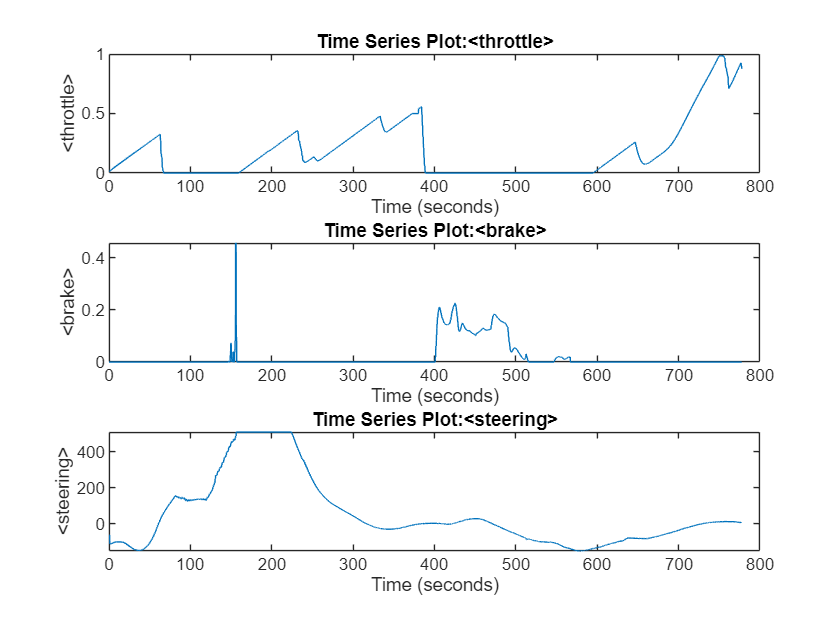

pause(0.5)
beamng.cosim.stopCoupling(vehicle);

% plot result
figure
subplot 311
plot(out.throttle0)
subplot 312
plot(out.brake0)
subplot 313
plot(out.steering0)

## Demo 1

mode = 1; %#ok
vehicle.teleport(py.tuple([-920, 870, 75]), py.tuple([0, 0, 1, -1]));
pause(0.5)
beamng.cosim.startCoupling(vehicle);
options = simset('SrcWorkspace', 'current', 'Timeout', Demo_duration); % Set timeout to Demo_duration in seconds
out = sim(simulink_model, [], options);

Bus Object for Output Port 2: body_state
Bus Object for Output Port 1: driver_controls
Bus Object for Input Port 1: input
Bus Object for Output Port 3: vehicle_status
Bus Object for Output Port 4: wheelFL
Bus Object for Output Port 5: wheelFR
Bus Object for Output Port 6: wheelRL
Bus Object for Output Port 7: wheelRR
# Debug Logging enabled for block combined_model/FMU3
Log from FMU: [category:logEvents, status:fmi3OK] Connection opened at time: 0.000000
Log from FMU: [category:logEvents, status:fmi3OK] Configured the UDP socket to (127.0.0.1:64890->127.0.0.1:64891)
Log from FMU: [category:logEvents, status:fmi3OK] Closed UDP connection, FMU terminating.


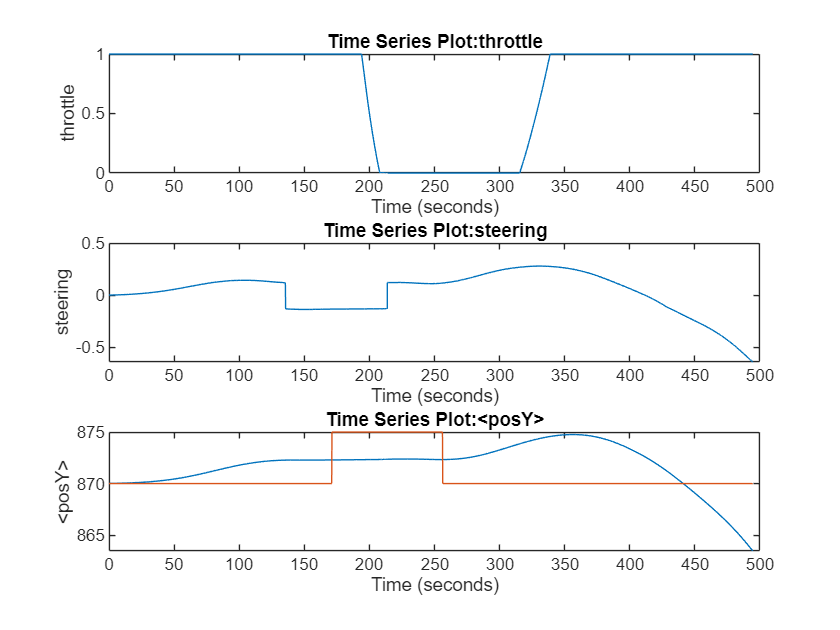

pause(0.5)
beamng.cosim.stopCoupling(vehicle);

% plot result
figure
subplot 311
plot(out.throttle1)
subplot 312
plot(out.steering1)
subplot 313
plot(out.posy1)
hold on
plot(out.targety1)

## Demo 2

mode = 2; %#ok
vehicle.teleport(py.tuple([-920, 767, 92.5]), py.tuple([0, 0, 1, -1]));
pause(0.5)

beamng.cosim.startCoupling(vehicle);
options = simset('SrcWorkspace', 'current', 'Timeout', Demo_duration); % Set timeout to Demo_duration in seconds
out = sim(simulink_model, [], options);

Bus Object for Output Port 2: body_state
Bus Object for Output Port 1: driver_controls
Bus Object for Input Port 1: input
Bus Object for Output Port 3: vehicle_status
Bus Object for Output Port 4: wheelFL
Bus Object for Output Port 5: wheelFR
Bus Object for Output Port 6: wheelRL
Bus Object for Output Port 7: wheelRR
# Debug Logging enabled for block combined_model/FMU3
Log from FMU: [category:logEvents, status:fmi3OK] Connection opened at time: 0.000000
Log from FMU: [category:logEvents, status:fmi3OK] Configured the UDP socket to (127.0.0.1:64890->127.0.0.1:64891)
Log from FMU: [category:logEvents, status:fmi3OK] Closed UDP connection, FMU terminating.


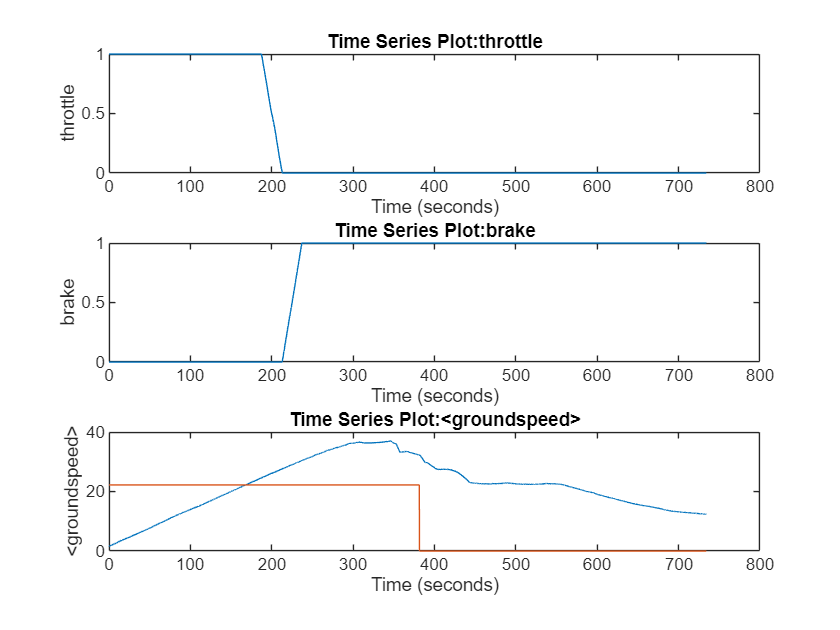

pause(0.5)
beamng.cosim.stopCoupling(vehicle);

% plot result
figure
subplot 311
plot(out.throttle2)
subplot 312
plot(out.brake2)
subplot 313
plot(out.v2)
hold on
plot(out.targetv2)

## Demo 3

mode = 3;
vehicle.teleport(py.tuple([-318, 371, 101.5]), py.tuple([0, 0, 1, 0.4]));
pause(0.5)
vehicle.ai.set_mode("span")
beamng.cosim.startCoupling(vehicle);
options = simset('SrcWorkspace', 'current', 'Timeout', Demo_duration); % Set timeout to Demo_duration in seconds
out = sim(simulink_model, [], options);

Bus Object for Output Port 2: body_state
Bus Object for Output Port 1: driver_controls
Bus Object for Input Port 1: input
Bus Object for Output Port 3: vehicle_status
Bus Object for Output Port 4: wheelFL
Bus Object for Output Port 5: wheelFR
Bus Object for Output Port 6: wheelRL
Bus Object for Output Port 7: wheelRR
# Debug Logging enabled for block combined_model/FMU3
Log from FMU: [category:logEvents, status:fmi3OK] Connection opened at time: 0.000000
Log from FMU: [category:logEvents, status:fmi3OK] Configured the UDP socket to (127.0.0.1:64890->127.0.0.1:64891)
Log from FMU: [category:logEvents, status:fmi3OK] Closed UDP connection, FMU terminating.


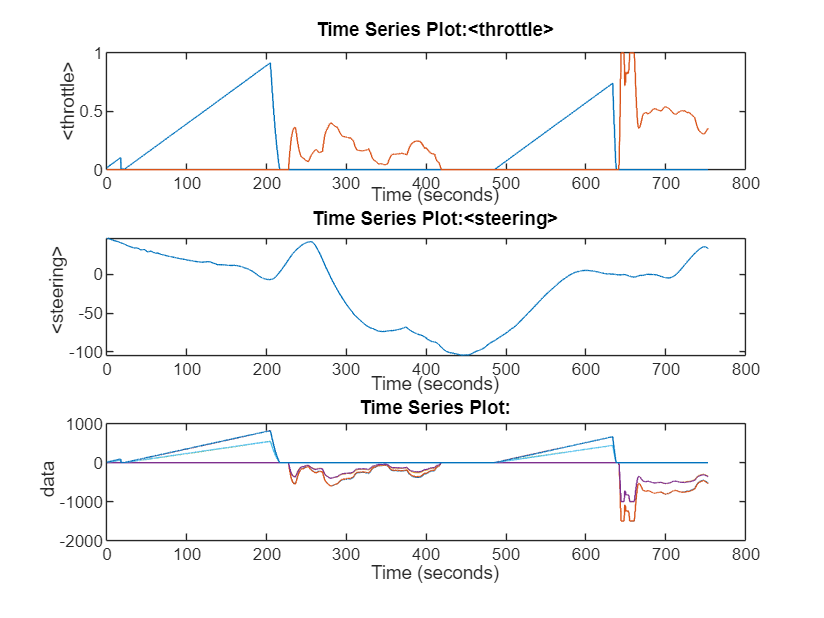


pause(0.5)
beamng.cosim.stopCoupling(vehicle);

% plot result
figure
subplot 311
plot(out.throttle3)
hold on
plot(out.brake3)
subplot 312
plot(out.steering3)
subplot 313
plot(out.torques3)

bng.close()
close_system(simulink_model)